# UKF for motors

Parameters:

- R   - coil resistance

- Ke - back emf

- Tf  - friction torque

- Df  - viscous dampening

- d   - drag constant

- J   - inertia

Equations: 

NOTE: this is the equation implemented in simulink, and the equation in the word document is different (further adding to my confusion) 

- omega_dot = 1/J * (Ke*i_batt - d*omega^2 - Df*omega - Tf

Inputs:

- voltage

% load the data files
load voltage;
load current;
load omega;
load time;
load motorParams;
disp(motorParams);

     R: 0.8000
    Ke: 0.0068
    Tf: 1.0000e-08
    Df: 0
     d: 1.6000e-08
     j: 4.9000e-06



#### Plot the results from the simulink model (ground truth)

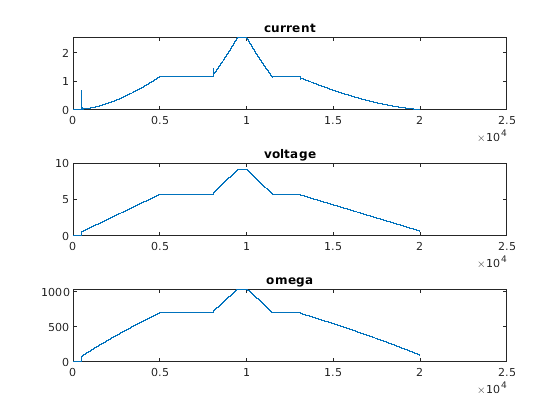

f1 = figure(1); clf;
subplot(3,1,1);
plot(current);
title("current");

subplot(3,1,2);
plot(voltage);
title("voltage");

subplot(3,1,3);
plot(omega);
title("omega");

% initialize empty vectors for comparison with the simulation vectors
ssOmega = zeros(length(omega),1);
ssCurrent = zeros(length(current),1);

% get motor params
R  = motorParams.R;
j  = motorParams.j;
Ke = motorParams.Ke;
Tf = motorParams.Tf;
Df = motorParams.Df;
d  = motorParams.d;

% state equation matricies
A = [];
B = [];
C = [];
D = [];

% noise matricies, dimensions? what should they really be?
processNoise = [.1];
sensorNoise  = [.1];

% only state variable is omega?
x = [];

% using data from the simulink model, simulate the system in state space
% equation form (this will be used in the UKF)
for k=1:length(time)
    u = voltage(k);
    
    x_dot = stateEqn(x, A, B, u, processNoise);
    
    [ssOmega(k), ssCurrent(k)] = outputEqn(x, C, D, u, sensorNoise);
    
    x = x_dot;
end

#### Plot the results from the statespace equations against the simulink results 

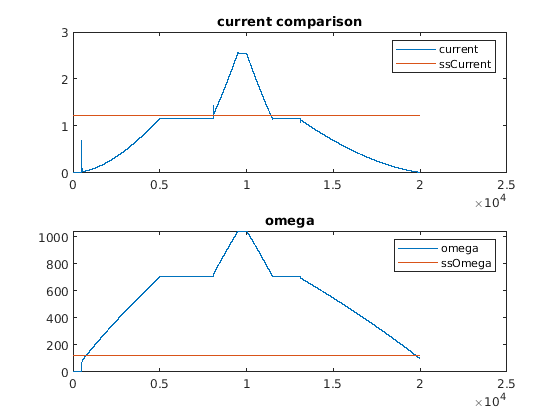

f2 = figure(2); clf;
subplot(2,1,1);
plot(current); hold on;
plot(ssCurrent); hold off;
title("current comparison");
legend("current", "ssCurrent");

subplot(2,1,2);
plot(omega); hold on;
plot(ssOmega); hold off;
title("omega");
legend("omega", "ssOmega");

## Functions

- stateEqn

- outputEqn

function [x_dot] = stateEqn(x, A, B, u, noise)



x_dot = [x];

end





function [omega, current] = outputEqn(x, C, D, u, noise)



omega = 123;
current = 1.23;

end








